# Numerical Integration of a Genetic Switch

MB&B/MCDB 361/562 Modeling Biological Systems, Spring 2024, Class 3, Joe Howard 

GeneticSwitchCLass.mlx

This script makes a variety of plots for the solutions of the equation for the genetic switch from Classes 2 and 3: 


$${\frac{dx}{dt}}=\dot{x}=r-\alpha{x}+\beta{\frac{x^n}{x^n+x_M^n}}$$


in which the  protein x feeds back positively on its own expression.

*r:           *basal rate of transcription (and translation)

alpha:   protein decay

beta:     transcritptional activation feedback strength

xM:       concentration at half-maximal feedback

n:         Hill coefficient

## Parameters

param is a vector that can be passed to functions

param.r = 0.1; % in concentration/time (uM/minute)
param.beta = 3; % same units (beta)
param.x_M = 30; % in concentration (uM) (x_M)
param.n = 4; % cooperativity/Hill function steepness 
param.alpha = 0.05; % in units of 1/time (1/minutes) (alpha)

paramsave = param; %save this array of parameters

## Increasing and decreasing of concentration changes

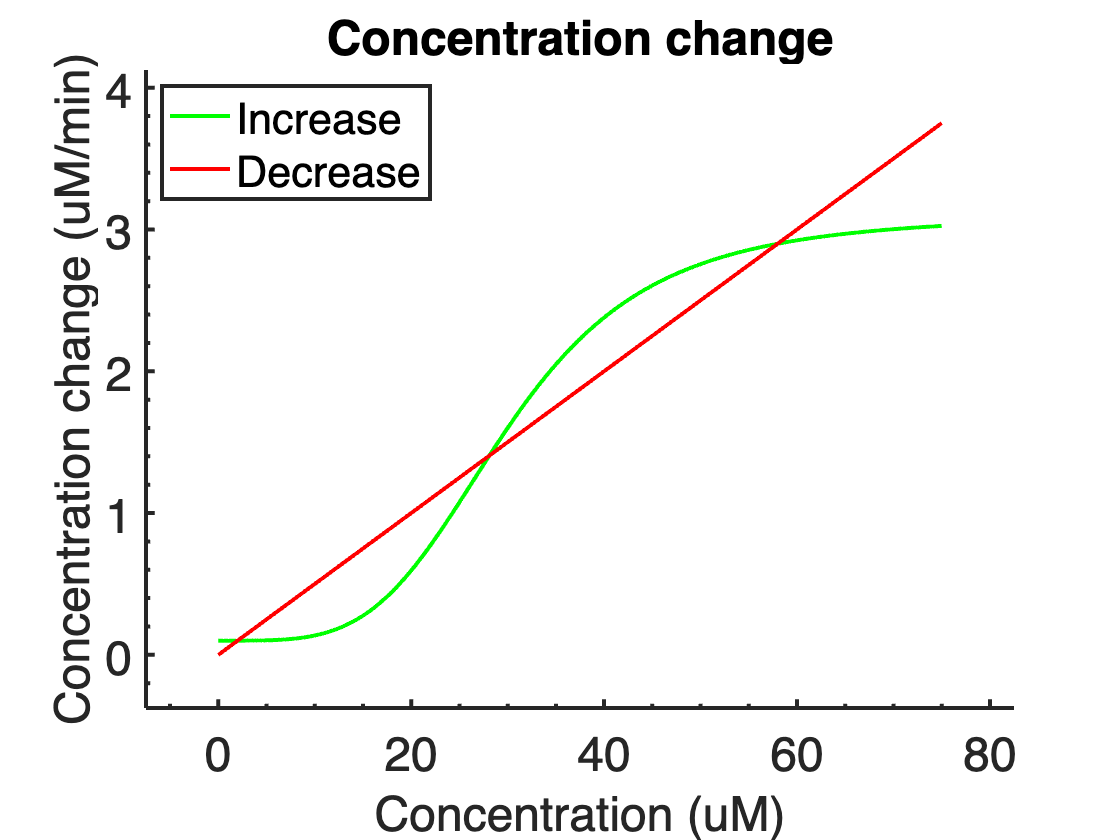

x0=0; % minimum x
xmax=param.x_M*2.5; %maximum value of x
dx=xmax/1000; %x increment
x=x0:dx:xmax; %array of x
%diffx=differential_equation(0,x,param);
diffx_plus=param.r + param.beta*x.^param.n./(param.x_M.^param.n + x.^param.n);
diffx_minus= param.alpha*x;

figure;
hold on;
zoom on; %allows your to zoom intoi the curves
plot(x,diffx_plus,'g-');
plot(x,diffx_minus,'r-');
xlabel('Concentration (uM)');
ylabel('Concentration change (uM/min)');
title('Concentration change');
legend('Increase','Decrease','Location','NorthWest');
PrettyFig;

## Dependence of fixed points on *r*

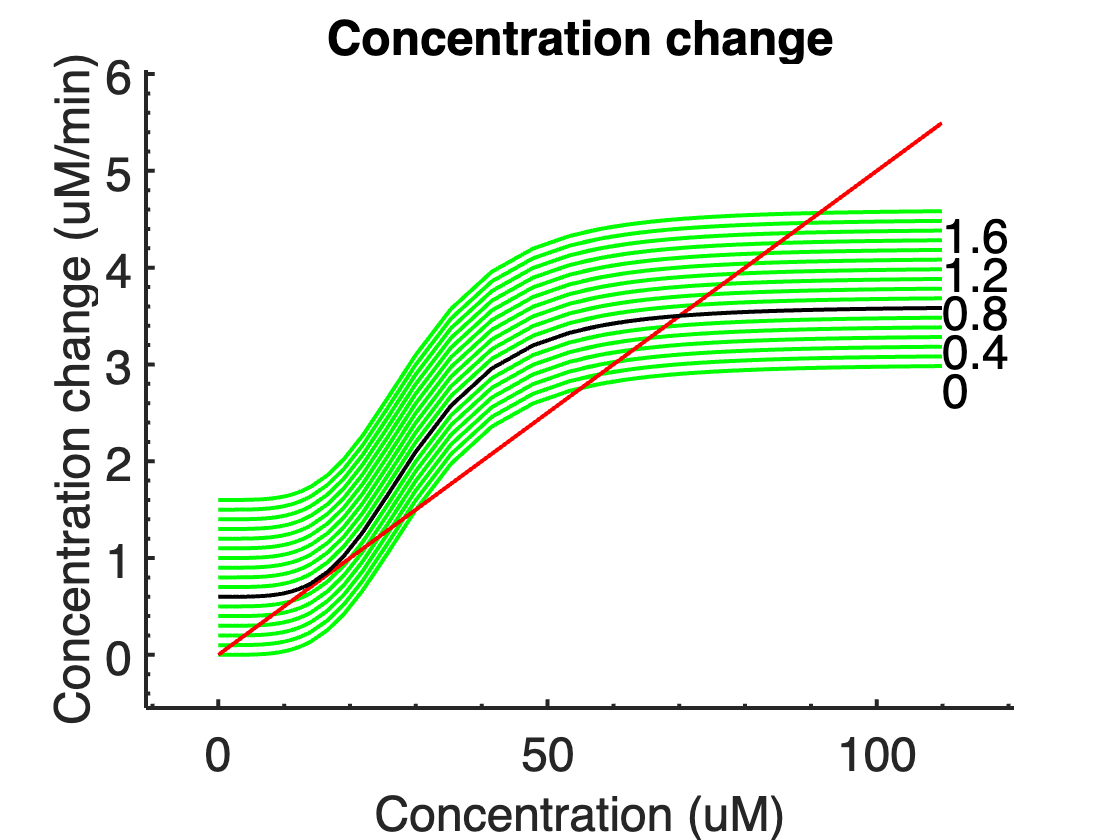

r_vals = 0:0.1:1.6; %an array of r values
figure;
hold on;
zoom on;
xlabel('Concentration (uM)');
ylabel('Concentration change (uM/min)');
title('Concentration change');
% legend('Increase','Decrease','Location','NorthWest');

for ii=1:length(r_vals)
    r_val = r_vals(ii);

    diffx_plus=r_val + param.beta*x.^param.n./(param.x_M.^param.n + x.^param.n);
    diffx_minus= param.alpha*x;

    plot(x,diffx_plus,'g-');
    plot(x,diffx_minus,'r-');
    if( ii-1)/4==round((ii-1)/4)
    text(max(x),diffx_plus(end),num2str(r_val));
    end
end

% [Question 1].
%See Question1: insert modified lines 37 (with value of r) and 40)
diffx_plus=0.6 + param.beta*x.^param.n./(param.x_M.^param.n + x.^param.n);
plot(x,diffx_plus,'k-');

PrettyFig;

QUESTION 1: at approximately what value of r_basal does the system transition from 3 to 1 fixed point? Demonstrate this by plotting x (in black = "k") for the value of r where the green curve kisses the red one (insert the code at the end of the section above (but before PrettyFig). 

The curves kiss each other at about **r = 0.6**.

## Numerical Integration with Euler's Method

This equation is difficult to solve analytically, so let's integrate numerically it to find solutions as a function of t. The function 'differential_equation' evaluates dx/dt given the parameters of the equation in param (look at it). 

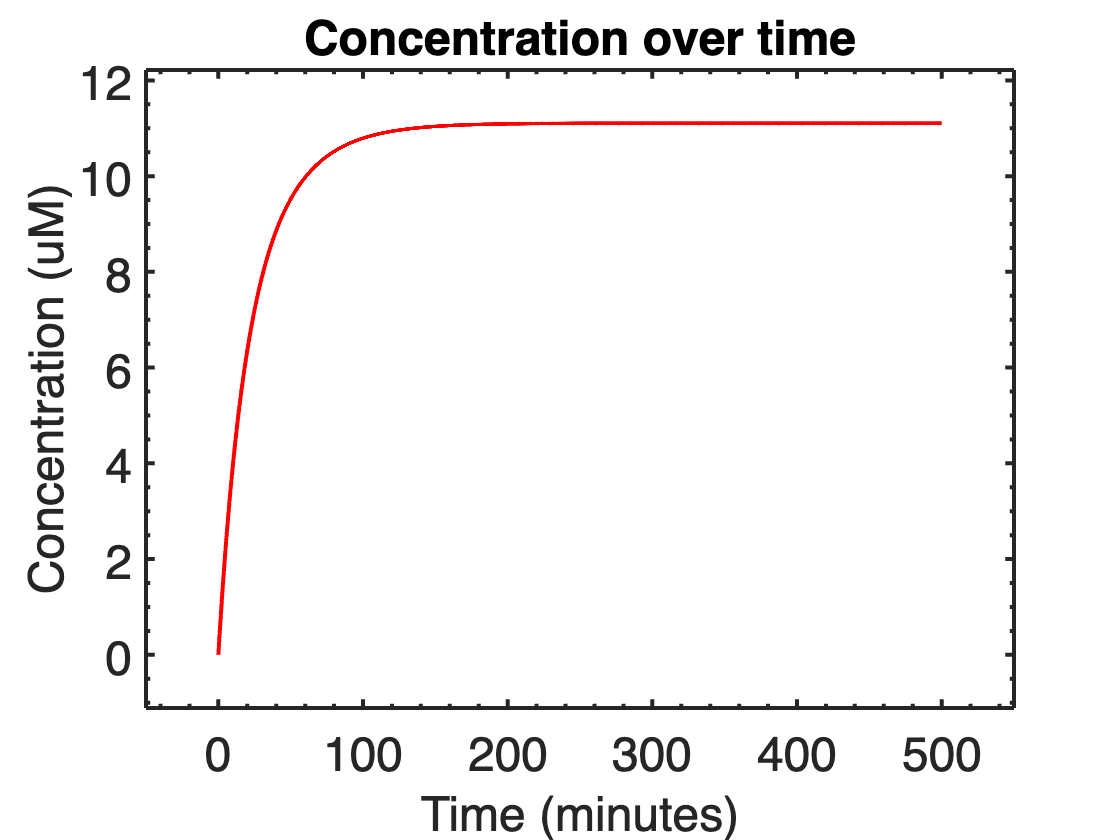

dt = 0.1; % 0.1 minute
T0 = 0; % initial time
Tf = 500; % final time = 500 minutes

tpositions = T0:dt:Tf;
x = zeros(size(tpositions)); % array of x values as function of time (initialized to zero)
x(1) = 0; % starting position for x
%x(1) = 100; % starting position for x
for ii=2:length(tpositions)
    x(ii) = x(ii-1) + dt*differential_equation(tpositions(ii),x(ii-1),param);
end

% Now, we can plot these up
figure;
plot(tpositions,x,'r-');
xlabel('Time (minutes)');
ylabel('Concentration (uM)');
title('Concentration over time');
PrettyFig;

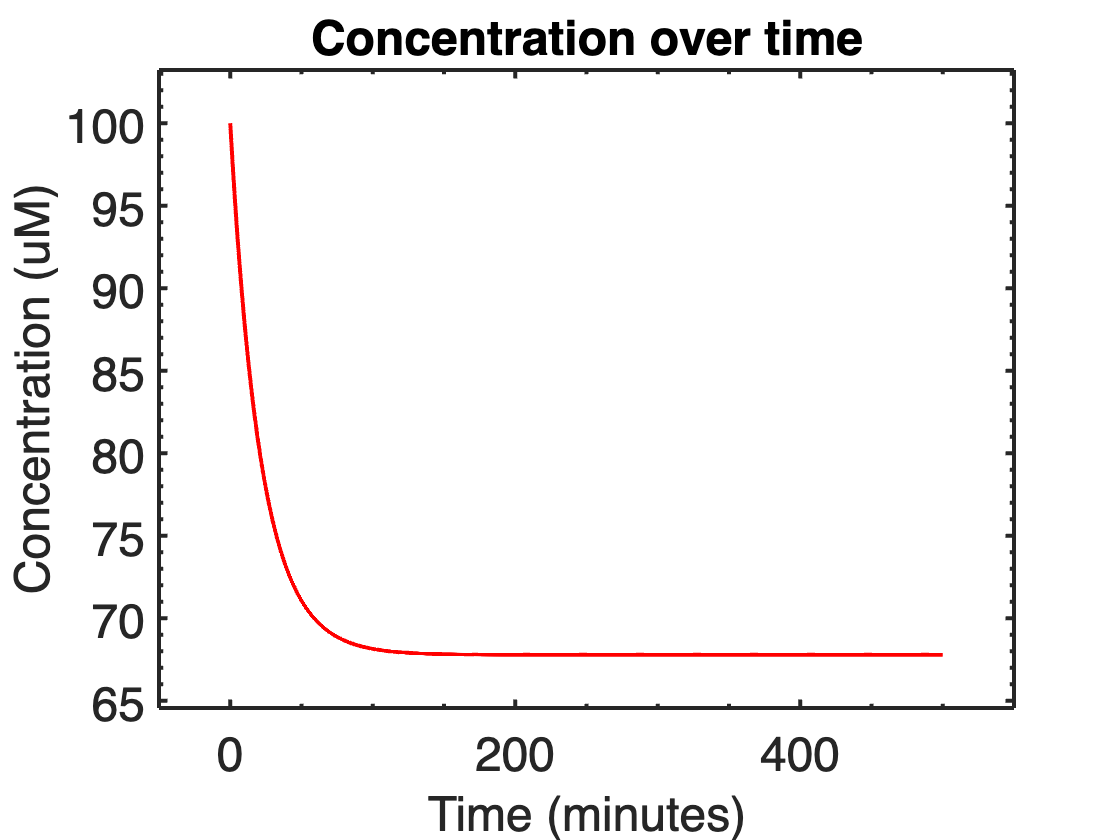

% [QUESTION 4] integrate, starting at concentration of 100.
x(1) = 100; % starting position for x
for ii=2:length(tpositions)
    x(ii) = x(ii-1) + dt*differential_equation(tpositions(ii),x(ii-1),param);
end

% Now, we can plot these up
figure;
plot(tpositions,x,'r-');
xlabel('Time (minutes)');
ylabel('Concentration (uM)');
title('Concentration over time');
PrettyFig;

QUESTION 2. When x0 is small (0), the concentration converges to a low steady-state value (x_SS). Estimate x_SS by assuming that the feedback term is small and set dx/dt=0 in the differential equation.

**x_SS evaluates to 20** with the assumption that the feedback term is 0. This is close to the value obtained in the graph above. (Numerical working attached in PDF document).

QUESTION 3. When the initial value of x is large, then x_SS is also large. Confirm this by assuming that $\textrm{x0}\gg x_M$ in the differential equation so that the feedback term is approximately beta. Calculate x_SS. 

**x_SS evaluates to 62** with the assumption that the feedback term is exactly beta. This is close to the value obtained in the graph above. (Numerical working attached in PDF document).

QUESTION 4. Plot the curve by choosing *x*(1)=100 on line 57. 

## Convergence to the two steady-state values depends on the basal transcription rate 

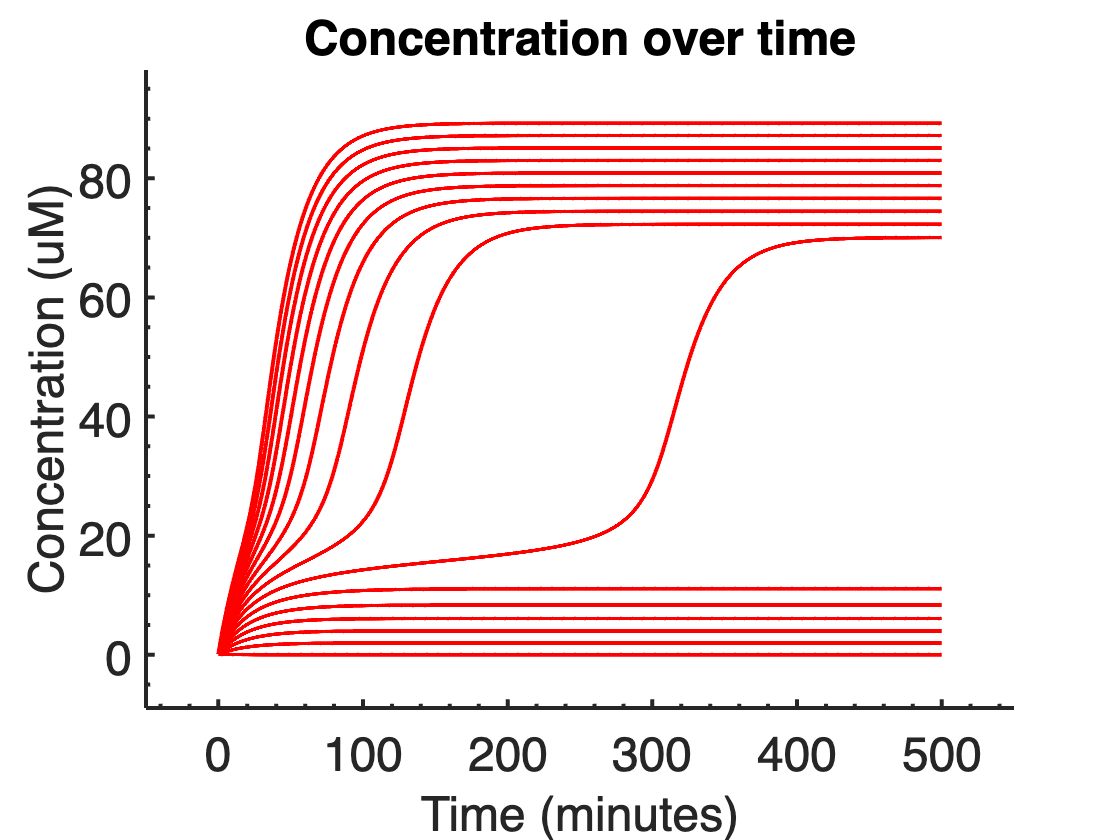

params = param; %new parameter array with variable r's
r_vals = 0:0.1:1.5; %an array of r values

figure; hold on;
xlabel('Time (minutes)');
ylabel('Concentration (uM)');
title('Concentration over time');

for ii=1:length(r_vals)
    params.r = r_vals(ii);
    
    x(1) = 0.1; % starting position for x

    for jj=2:length(tpositions)
        x(jj) = x(jj-1) + dt*differential_equation(tpositions(jj),x(jj-1),params);
    end
    
    plot(tpositions,x,'r-');

end
PrettyFig;

QUESTION 5:  Why, just after r is raised above its critical value, does the time trace seem to have two plateaus, before rising to a final, high value of x? 

At the critical value of r, the unstable and lower stable fixed points merge into one. When r is raised slightly above this value, the decrease and increase rates are still very close near the point where the curves kissed; the increase rate slightly higher than the decrease rate. Hence, although not at a stable point per se, the rise in concentration is very slow as the net increase rate is very low. As the concentration rises, the rate curves diverge apart making the net increase rate higher and causing a sharper increase in concentration until the system reaches the next stable fixed point.

## Family of curves for different starting points

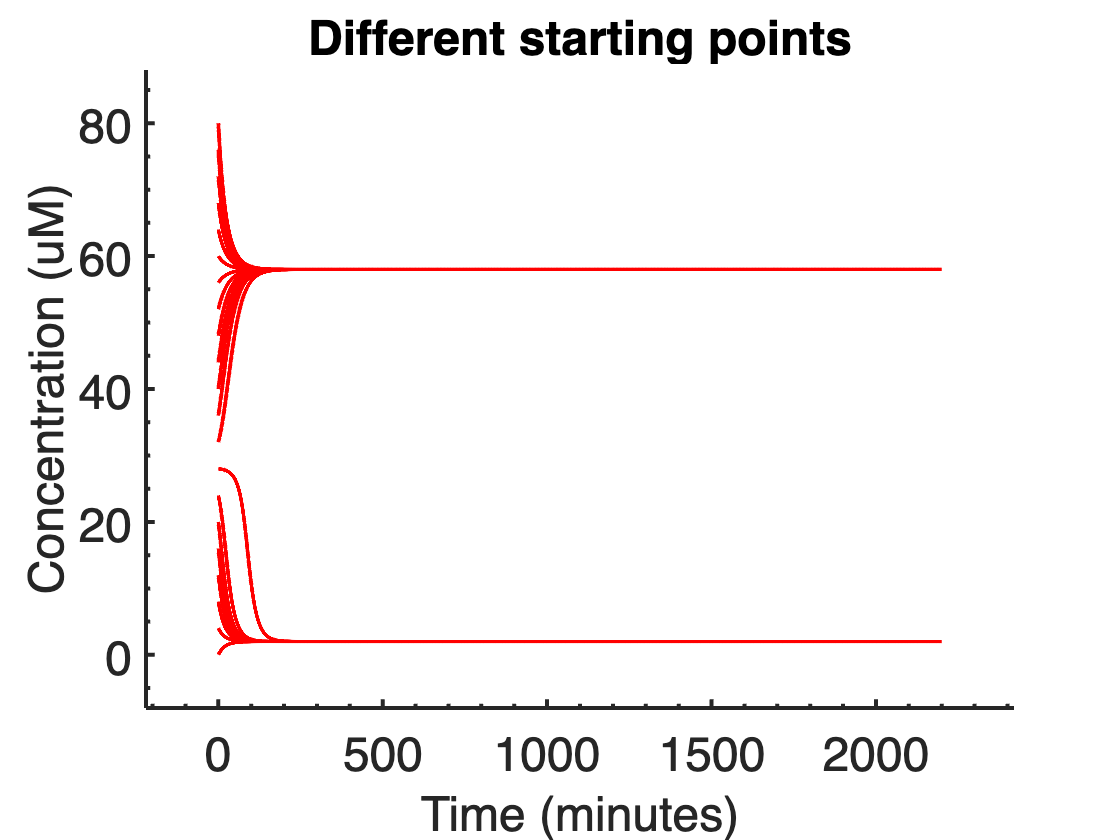

param = paramsave; %revert to original parameters

x0array = 0:4:80;
xarray = zeros(length(x0array),length(tpositions));

for jj=1:length(x0array)
    x(1) = x0array(jj); % starting position for x; updates each time
    for ii=2:length(tpositions)
        x(ii) = x(ii-1) + dt*differential_equation(tpositions(ii),x(ii-1),param);
    end
    xarray(jj,:) = x; % store each one for plotting later
end

figure; hold on;
plot(tpositions,xarray,'r-');
xlabel('Time (minutes)');
ylabel('Concentration (uM)');
title('Different starting points');

PrettyFig;

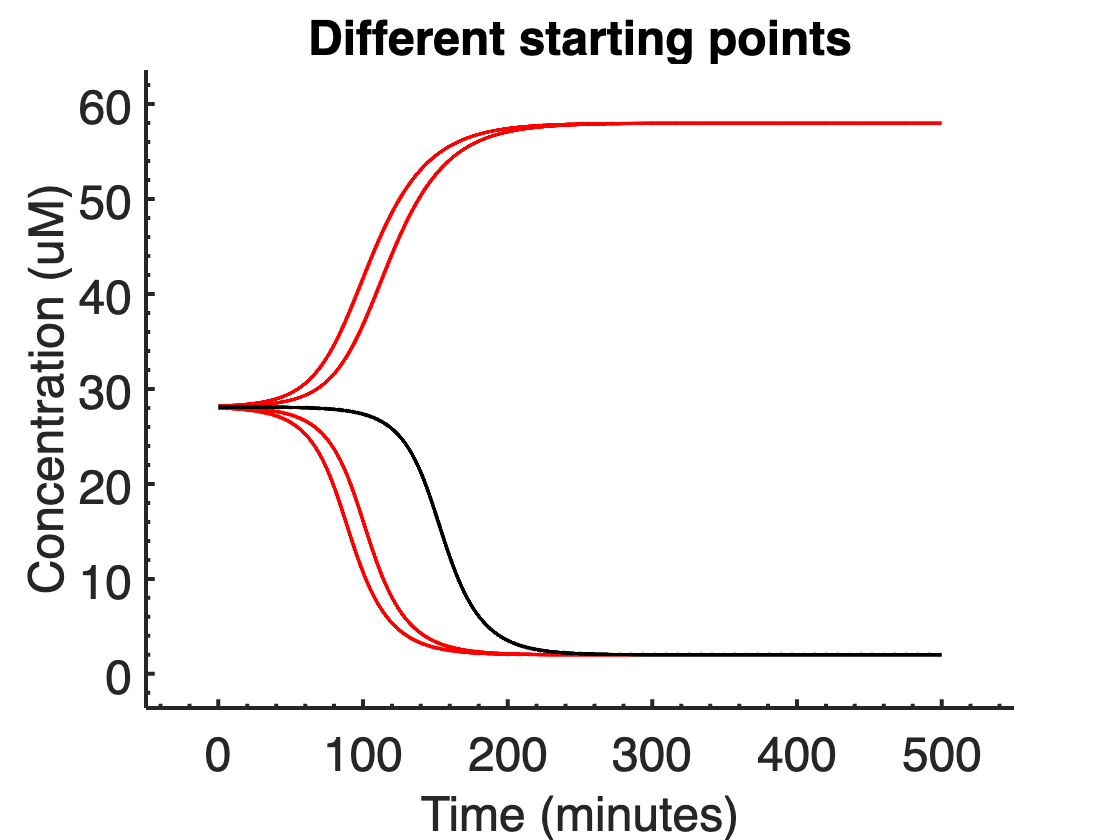

% [Question 6].
%enter your code here. You need to write lines 97-102 with the intial value
%of x(1) that is close to the bifurcation.
x0array = 28:0.05:28.2;
xarray = zeros(length(x0array),length(tpositions));

for jj=1:length(x0array)
    x(1) = x0array(jj); % starting position for x; updates each time
    for ii=2:length(tpositions)
        x(ii) = x(ii-1) + dt*differential_equation(tpositions(ii),x(ii-1),param);
    end
    xarray(jj,:) = x; % store each one for plotting later
end

clf;
figure; hold on;
plot(tpositions,xarray,'r-');
plot(tpositions,xarray(3,:) ,'k-');
xlabel('Time (minutes)');
ylabel('Concentration (uM)');
title('Different starting points');

PrettyFig;

QUESTION 6: what determines whether a starting point ends up high or low? By looking at the first plot you made of dx/dt against x, find the value x  at which the split. If you make this x(1) then x(t) will increase or decrease very slowly. Plot this curve in black (see lines 109 and 110 above).

The relative positions of the stable fixed point and starting point determines whether the end concentration goes higher or lower. This fixed point occurs at about **x = 28.1**. Accordingly, the curve with starting concentration of 28.1 decreases slowly in comparison to curves above and below it.

## MatLab's numerical integrator ODE45

Okay, now the sad truth is that Euler's method is pretty unstable, especially if you get the dt wrong. There exist many better numerical methods. One easy way is to use ode45 in MATLAB, one of a family of integrating functions. The code below gets it working for you.

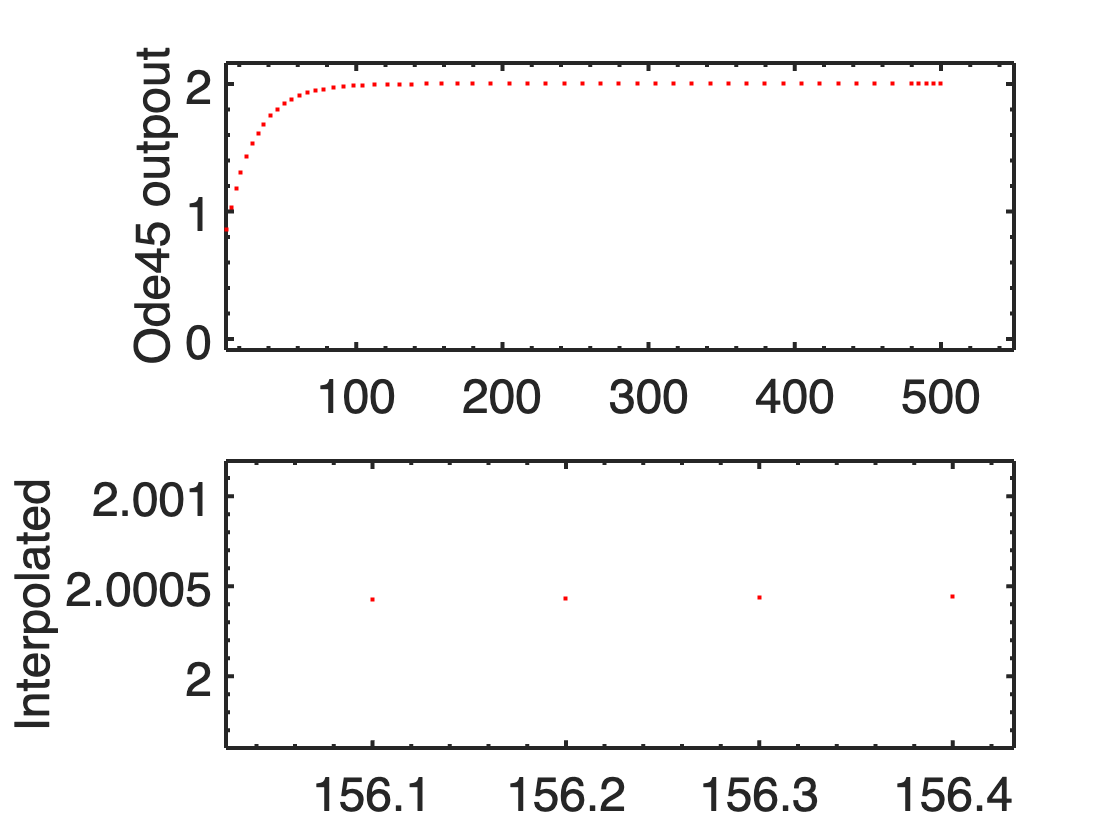

% first, just one of these...

x0 = 0;
% don't worry about the syntax for now -- it's a way to pass the parameters
% to the function
[tout,x] = ode45(@(t,y) differential_equation(t,y,param),[T0 Tf],x0);
% this function uses variable step sizes, but in general, we like uniform
% step sizes, so we interpolate the result here...
xi = interp1(tout,x,tpositions); %ode45 returned x(tout) where 
% tout times are not equally spaced. Interp1 spaces them into the tpositions 

% let's plot it up
figure;
zoom on;
subplot(2,1,1);
plot(tout,x,'r.'); %unequally time-spaced points. Plotting every point
ylabel('Ode45 outpout');
subplot(2,1,2);
zoom on;
plot(tpositions,xi,'r.'); %equally time spaced points
%plot(tpositions,xi,'r.','MarkerIndices',1:50:length(xi)); %equally time spaced points
%only plotting every 50th point for clarityxlabel('Time (minutes)');
ylabel('Interpolated');
PrettyFig;

Question 7: Zoom in to the lower graph several times (single clicks) till you can see the individual points. What is the time increment? 

The time increment is **0.1 units **on the interpolated plot.

## Now, again, let's do this for many starting positions, using ode45

this should go a little faster than Euler's method above...

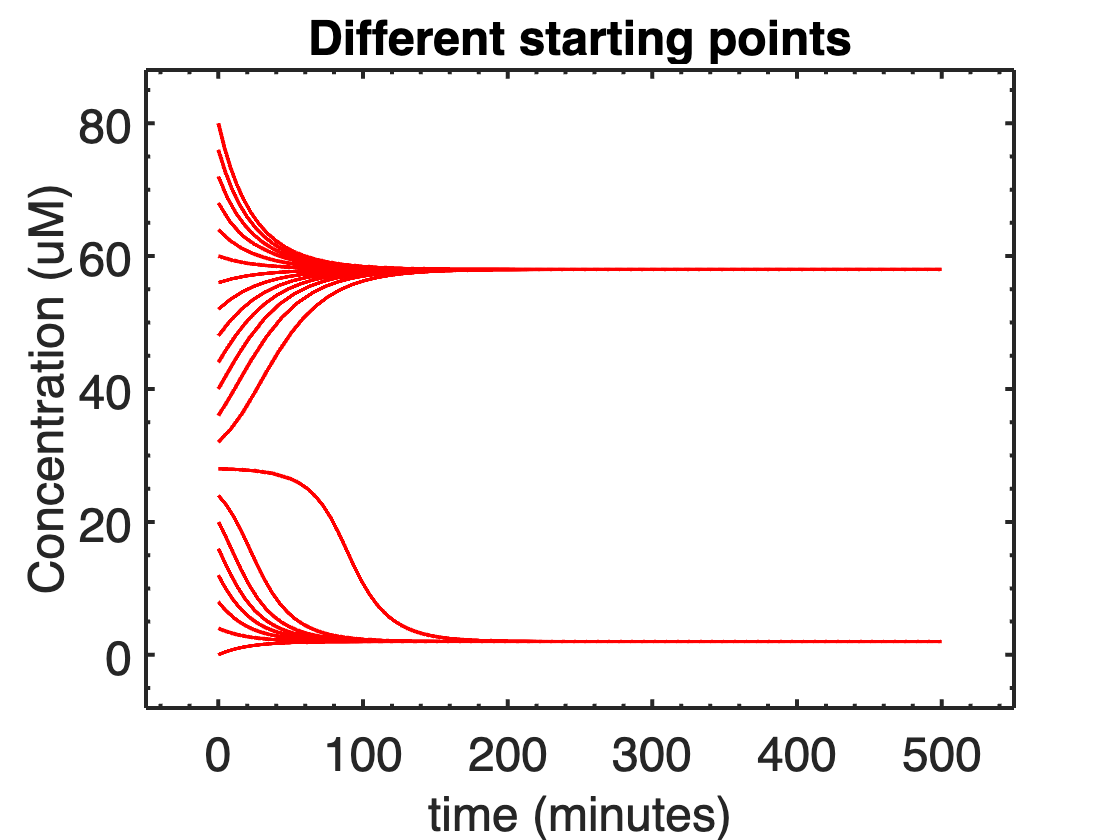

x0array = 0:4:80;
for jj=1:length(x0array)
    [tout,x] = ode45(@(t,y) differential_equation(t,y,param),[T0 Tf],x0array(jj));
    xarray(jj,:) = interp1(tout,x,tpositions); % store each one for plotting later
end

figure;
plot(tpositions,xarray,'r-');
xlabel('time (minutes)');
ylabel('Concentration (uM)');
title('Different starting points');
PrettyFig;

## Changing param.r as a function of time

The interesting thing is if we increase param.r_basal and then decrease it

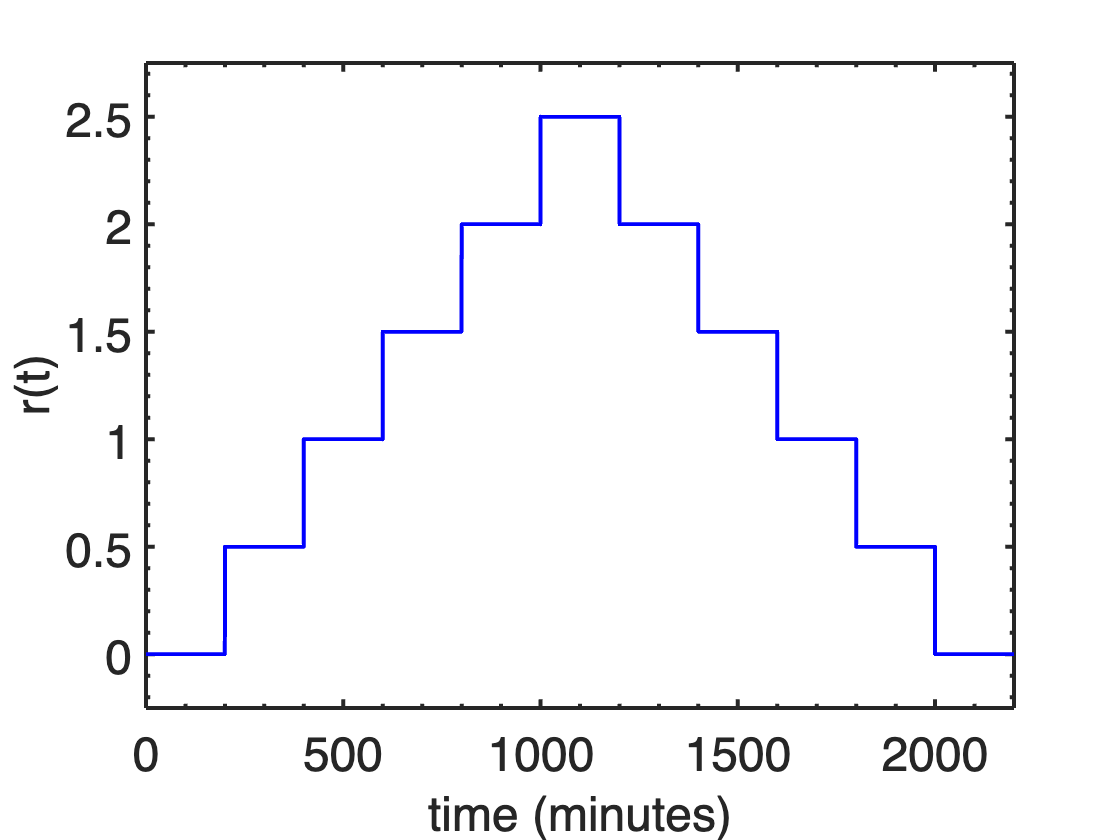

% Here is a function that allows you to step up the r_basal parameter over time,
% and then step it down again. Here is a plot of r_basal over time:

param = paramsave; % reload all the original values
param.r=0.5;
tpositions = 0:.1:2200;
rarray = 0:0.1:2200;
% plot r as a function of time
for ii=1:length(tpositions)
    rarray(ii)=param.r*steppingfunction(tpositions(ii));
end
figure;
plot(tpositions,rarray,'b-');
ylabel('r(t)');
xlabel('time (minutes)');
set(gca,'xlim',[min(tpositions) max(tpositions)]);
PrettyFig;

## Now solve with these values of r

This shows that the system has switched - returning r to zero and x is still at a high value (= ON)

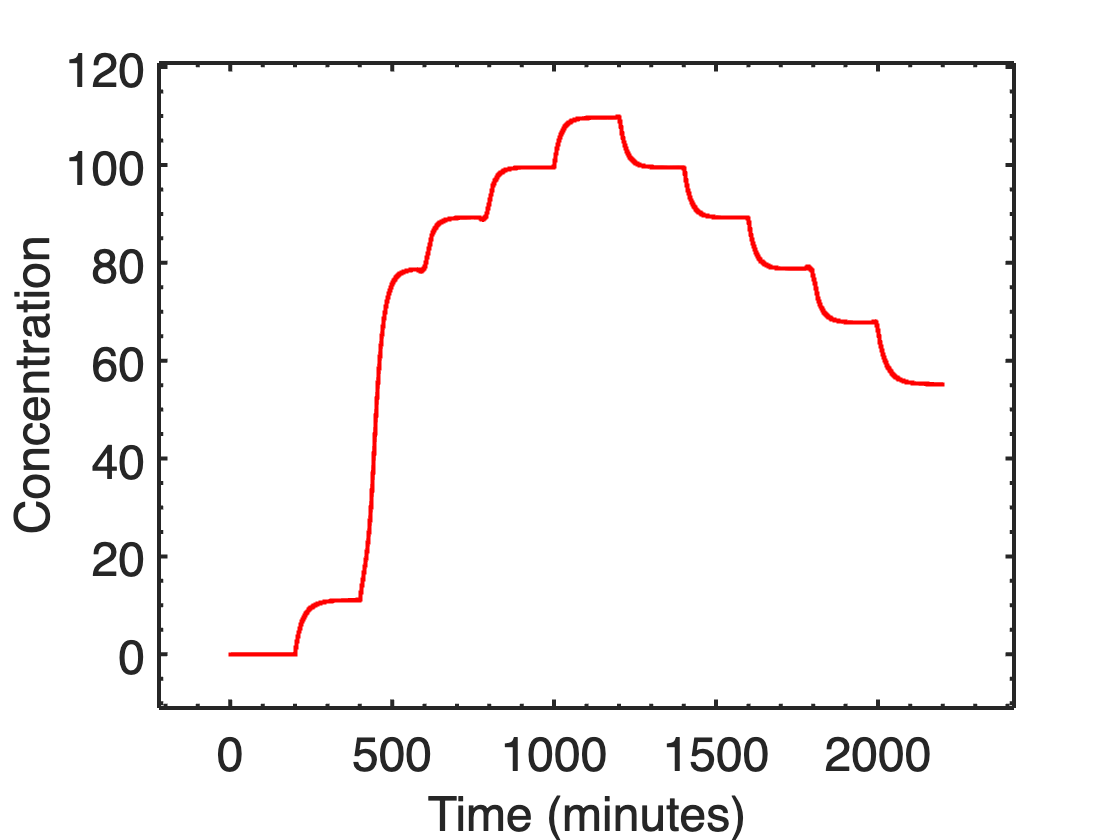

param = paramsave;
param.r = 0.5;
opts = odeset('MaxStep',0.5);
x0 = 0.05;
x0 = 0;
% don't worry about the syntax for now -- it's a way to pass the parameters
% to the function
[tout,x] = ode45(@(t,y) differential_equation_timedep(t,y,param),[T0 2200],x0);
% this function uses variable step sizes, but in general, we like uniform
% step sizes, so we interpolate the result here...
xi = interp1(tout,x,tpositions);

% let's plot it up
figure;
plot(tpositions,xi,'r.-');
xlabel('Time (minutes)');
ylabel('Concentration');
PrettyFig;